Displaying uncertainty due to stochastic error: 

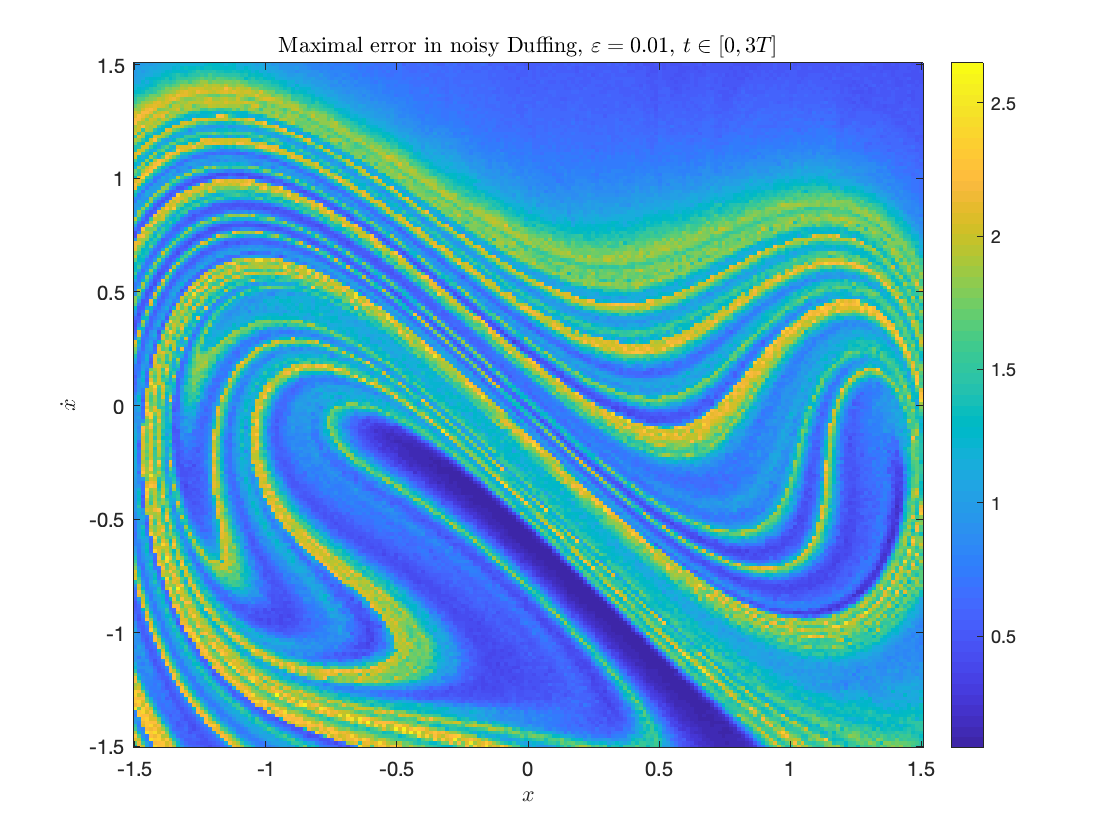

resolution = [200,200];

m = load('data/maxdevsSDE.mat');
maxdevs = m.maxdevs;
maxdevs =reshape(maxdevs, resolution);

domain = [-1.5, 1.5; -1.5, 1.5];
imagesc(domain(1,:), domain(2,:), maxdevs);
set(gca, 'YDir', 'normal');
colorbar;
title('Noisy Duffing, $\varepsilon =  0.01$', 'Interpreter', 'Latex');
xlabel('$x$', 'Interpreter', 'Latex');
ylabel('$\dot{x}$', 'Interpreter', 'Latex');
title('Maximal error in noisy Duffing, $\varepsilon =  0.01$, $t\in [0, 3T]$', 'Interpreter', 'Latex');
saveas(gca, 'pics/ResearchMeeting3/uncertaintyNoisyDuffing3Teps01.png');

Displaying uncertainty due to deterministic error $\varepsilon = 0.01$

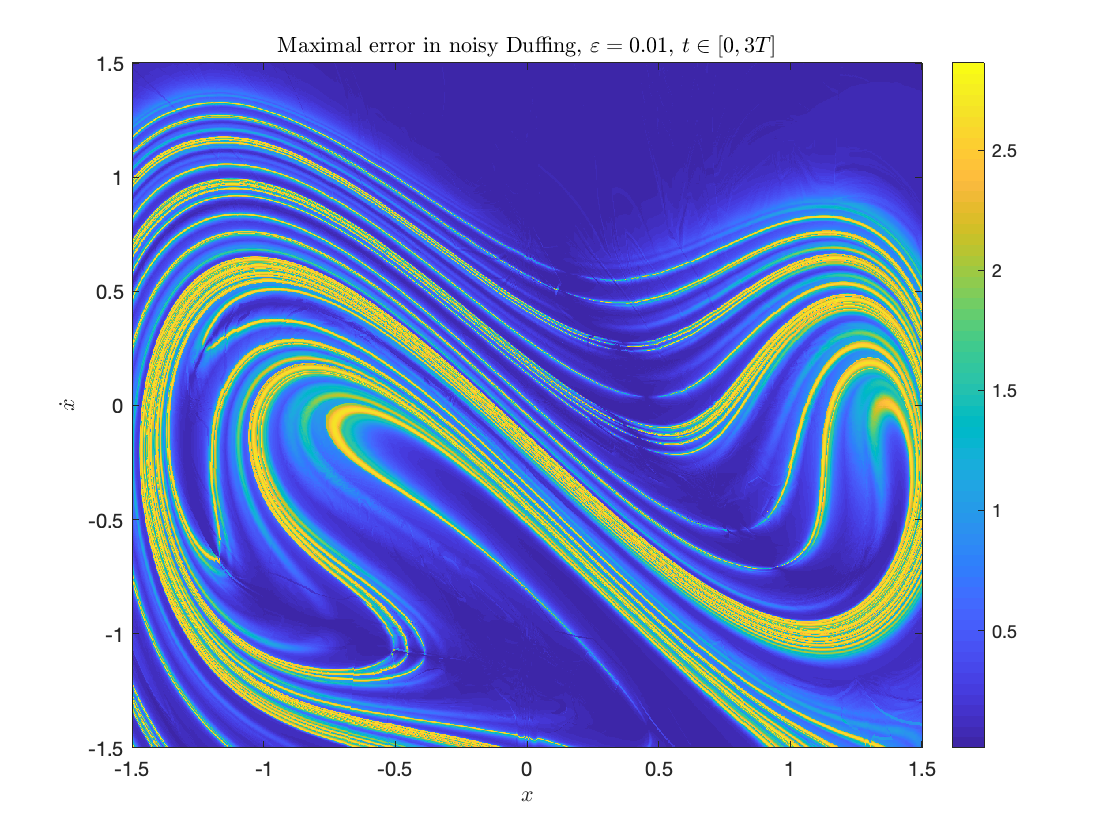

resolution = [1000,1000];

m = load('data/maxdevs.mat');
maxdevs = m.maxdevs;
maxdevs =reshape(maxdevs, resolution);

domain = [-1.5, 1.5; -1.5, 1.5];
imagesc(domain(1,:), domain(2,:), maxdevs);
set(gca, 'YDir', 'normal');
colorbar;
title('Duffing, $\varepsilon =  0.01$', 'Interpreter', 'Latex');
xlabel('$x$', 'Interpreter', 'Latex');
ylabel('$\dot{x}$', 'Interpreter', 'Latex');
title('Maximal error in noisy Duffing, $\varepsilon =  0.01$, $t\in [0, 3T]$', 'Interpreter', 'Latex');
saveas(gca, 'pics/ResearchMeeting3/uncertaintyDuffing3Teps01.png');

ic1 = [0.8604, -0.527];%, 3791.];
ic2 = [0.9835, -0.47];%, 128.]
T = 3*2*pi;
deltaT = T/100;
timeInterval = [0, T];
stepSize = deltaT;
lDerivative = @(t,y) d_phi(t,y,0, false);
%[t1, uncertAtTime1] = computeAlongTrajectory(lDerivative, ic1, timeInterval, stepSize );
%[t2, uncertAtTime2] = computeAlongTrajectory(lDerivative, ic2, timeInterval, stepSize );

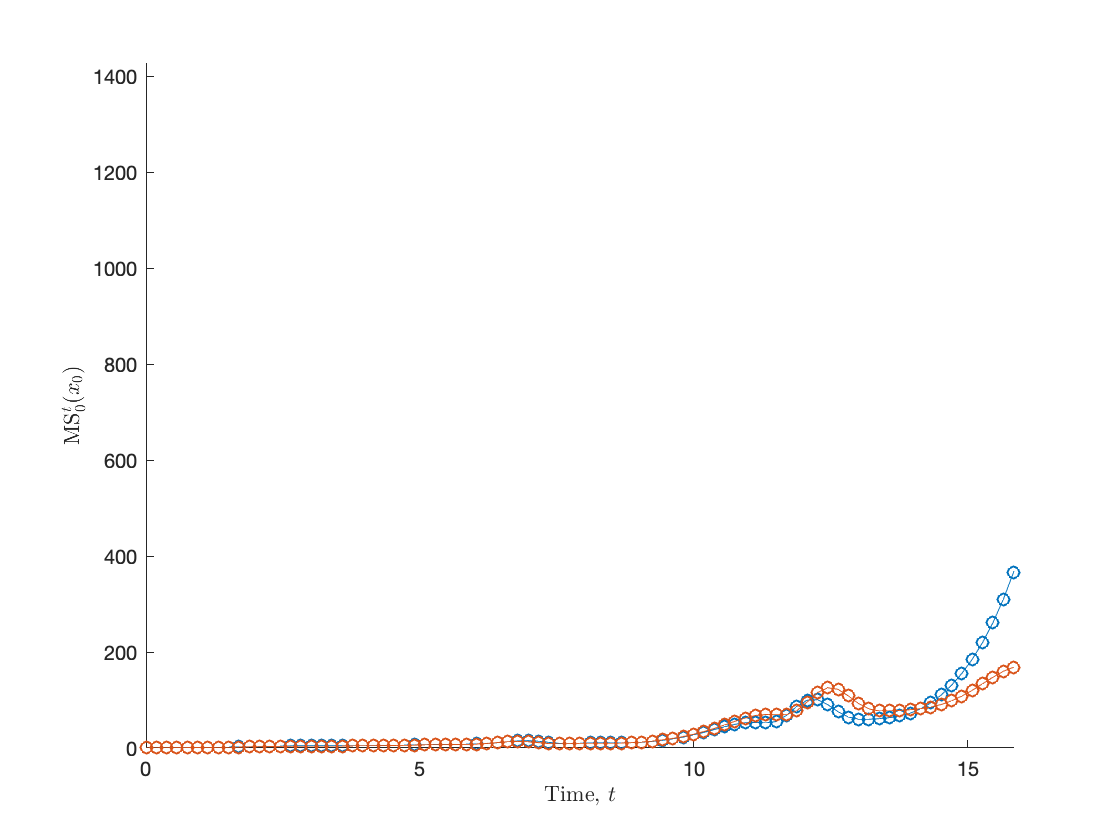

clf;
cla;
hold on;
plot(t1, uncertAtTime1, '-o');
plot(t2, uncertAtTime2, '-o');
xlabel('Time, $t$', 'Interpreter',"latex");
ylabel('MS$_0^{t}(x_0)$', 'Interpreter',"latex");

Bounds are valid for all t: Critical epsilon should be the value, for which the uncertainty first exceeds the model sensitivity

lDerivative = @(t,y,e, eov) d_phi(t,y,e, eov);
diffBound  = differenceFromBoundIsPositive(lDerivative, ic1, uncertAtTime1, t1, 2);
epsilons = logspace(-4, 2, 100);
isTrue = zeros(size(epsilons));
for i=1:length(epsilons)
   isOk = differenceFromBoundIsPositive(lDerivative, ic1, uncertAtTime1, t1, epsilons(i));
   isTrue(i) = isOk;
end

crit = epsilons(find(isTrue, 1))

crit = 1.5199

asdasd

pool.delete();
lDerivative = @(t,y,e, eov) d_phi(t,y,e, eov);
resolution = [100,100];
initialPosition = initialize_ic_grid(resolution,domain);
euler = parcluster('local');
pool = parpool(euler,18);

Starting parallel pool (parpool) using the 'local' profile ...



epsilons = logspace(-4, 2, 100);
criteps2 = zeros(length(initialPosition), 1);
T = 3*2*pi;
deltaT = T/10;
timeInterval = [0, T];
stepSize = deltaT;
parfor i = 1:length(initialPosition)
   x0 = initialPosition(i,:);
   lDerivative = @(t,y) d_phi(t,y,0, false);
   [t, uncertAtTime] = computeAlongTrajectory(lDerivative, x0, timeInterval, stepSize );
   lDerivative = @(t,y,e, eov) d_phi(t,y,e, eov);
   criteps(i) = getCriticalEpsilon(lDerivative,x0,uncertAtTime, t, epsilons);
end
pool.delete();
%save("criticalEps__.mat", "criteps2");

clf;
cla;
%% When the difference between the bound and the uncertainty is positive, the inequality fails
deriv = @(t,y) d_phi(t,y,0, false);
x0 = [1.3, -0.3];
time = 0:0.001*2*pi:2*pi;
[t, uncertAtTime] = computeAlongTrajectory(deriv, x0, [0,2*pi], 2*pi/100 );

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101



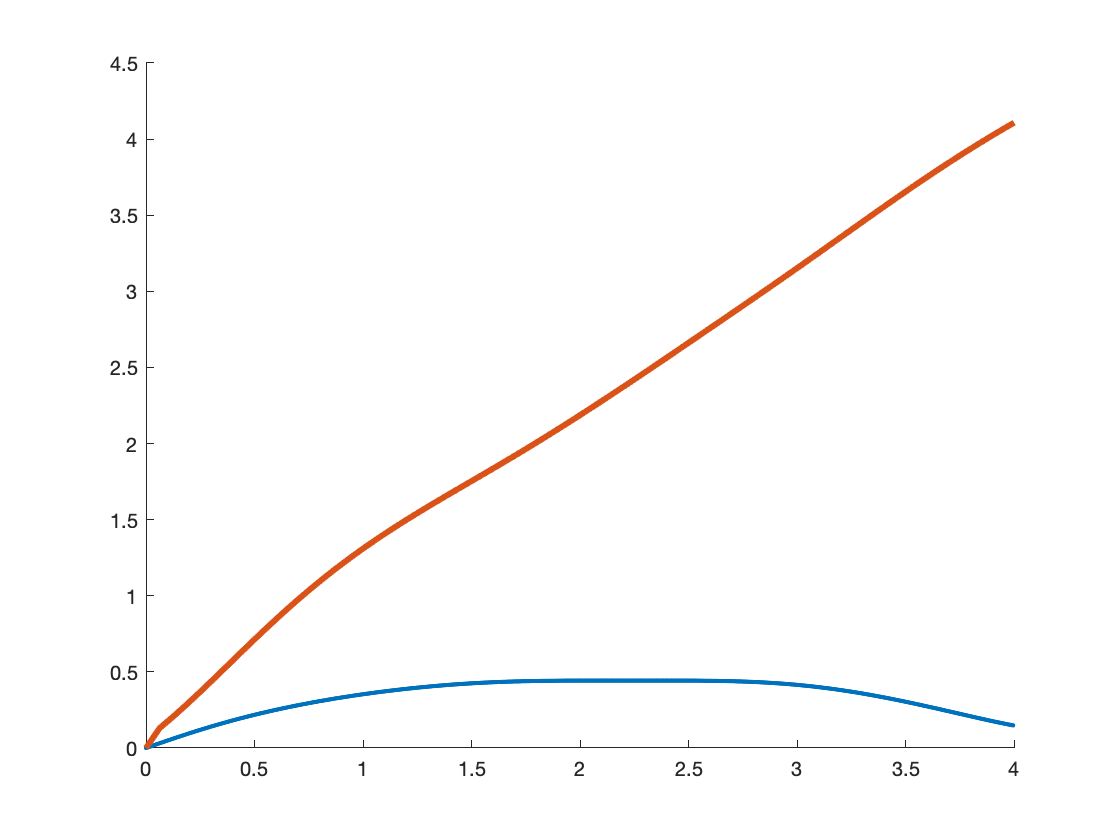


[~,trajectoryReference] = ode45(deriv, time, x0, odeset('RelTol',1e-8));

deriv = @(t,y) d_phi(t,y,0.5, false);
[~,trajectory] = ode45(deriv, time, x0, odeset('RelTol',1e-8));
diff = trajectory - trajectoryReference;
distance = sqrt(diff(:,1).^2 + diff(:,2).^2);
hold on;
plot(time, distance, '.-');
plot(t, uncertAtTime, '-', 'LineWidth',3);
xlim([0,4]);
hold off;


%difference = transpose(distance)- uncertAtTime;
%pos = difference > 0.0;
%isPositive = sum(pos);
%end

clf;
cla;
epsilon = 0.02;
%% When the difference between the bound and the uncertainty is positive, the inequality fails
f = @(t,x) d_phi(t,x,0, false);
g = @(t,x) epsilon;
dt = 1e-5*2*pi;
time = 0:dt:2*pi;


[time,yfref] = ode45(@(t,y) d_phi(t,y,0, false),time,x0); 
aggregate = zeros(size(yfref,1),1000);
hold on;
plot(t, uncertAtTime, '-', 'LineWidth',5);

for i = 1:1000
    yf = sde_euler(f,g,time,x0);
    diff = yf-yfref;
    aggregate(:,i) = sqrt(diff(:,1).^2 + diff(:,2).^2);
    plot(time, aggregate(:,i), '.');
    
    %plot(t, sqrt(diff(:,1).^2+diff(:,2).^2), '.');
end
plot(time, mean(aggregate, 2), '-', 'linewidth', 1, 'color', 'black');
xlabel('x');
ylabel('y');
xlim([0,1])

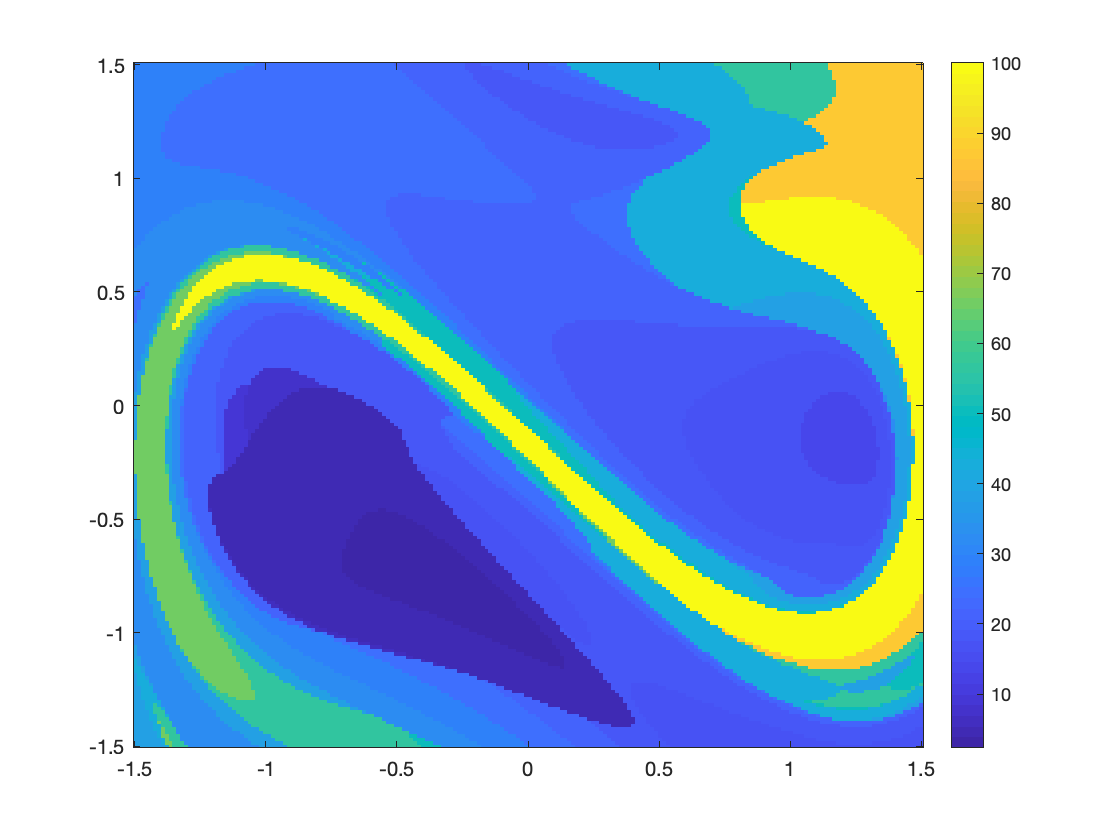

clf;
cla
domain = [-1.5, 1.5; -1.5, 1.5];

resolution = [200,200];

m = load("data/criticalEps__.mat");
criteps = m.criteps2;
criteps = reshape(transpose(criteps), resolution); 
imagesc(domain(1,:), domain(2,:), criteps);
set(gca, 'YDir', 'normal');
colorbar;

size(criteps)

ans =    200   200


deriv = @(t,y) d_phi(t,y,0, false);
x0 = [1.3, -0.3];
time = 0:0.001*2*pi:2*pi;
[t, uncertAtTime] = computeAlongTrajectory(deriv, x0, [0,2*pi], 2*pi/100 );

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101



save('t.mat',"t");
save('uncrtAtTime.mat',"uncertAtTime");

ic1 = [0.8604, -0.527];%, 3791.];
ic2 = [0.9835, -0.47];%, 128.]
T = 2*pi;
deltaT = T/20;
timeInterval = [0, T];
stepSize = deltaT;
lDerivative = @(t,y) d_phi(t,y,0, false);

[t1, uncertAtTime1] = computeAlongTrajectory(lDerivative, ic1, [0, 3.7700], stepSize );

     2

     1     2

     1     2

         0    0.3142    0.1577

     3

     1     3

     1     3

         0    0.6283    0.5032

     4

     1     4

     1     4

         0    0.9425    0.9030

     5

     1     5

     1     5

         0    1.2566    1.3232

     6

     1     6

     1     6

         0    1.5708    1.7017

     7

     1     7

     1     7

         0    1.8850    2.0261

     8

     1     8

     1     8

         0    2.1991    2.5482

     9

     1     9

     1     9

         0    2.5133    3.4085

    10

     1    10

     1    10

         0    2.8274    4.2667

    11

     1    11

     1    11

         0    3.1416    4.6833

    12

     1    12

     1    12

         0    3.4558    4.6288

    13

     1    13

     1    13

         0    3.7699    4.4956



[t2, uncertAtTime2] = computeAlongTrajectory(lDerivative, ic2, [0, 3.7700], stepSize );

     2

     1     2

     1     2

         0    0.3142    0.1666

     3

     1     3

     1     3

         0    0.6283    0.4801

     4

     1     4

     1     4

         0    0.9425    0.7766

     5

     1     5

     1     5

         0    1.2566    1.0880

     6

     1     6

     1     6

         0    1.5708    1.4023

     7

     1     7

     1     7

         0    1.8850    1.8117

     8

     1     8

     1     8

         0    2.1991    2.3924

     9

     1     9

     1     9

         0    2.5133    3.0706

    10

     1    10

     1    10

         0    2.8274    3.6389

    11

     1    11

     1    11

         0    3.1416    3.9250

    12

     1    12

     1    12

         0    3.4558    3.9742

    13

     1    13

     1    13

         0    3.7699    4.0044



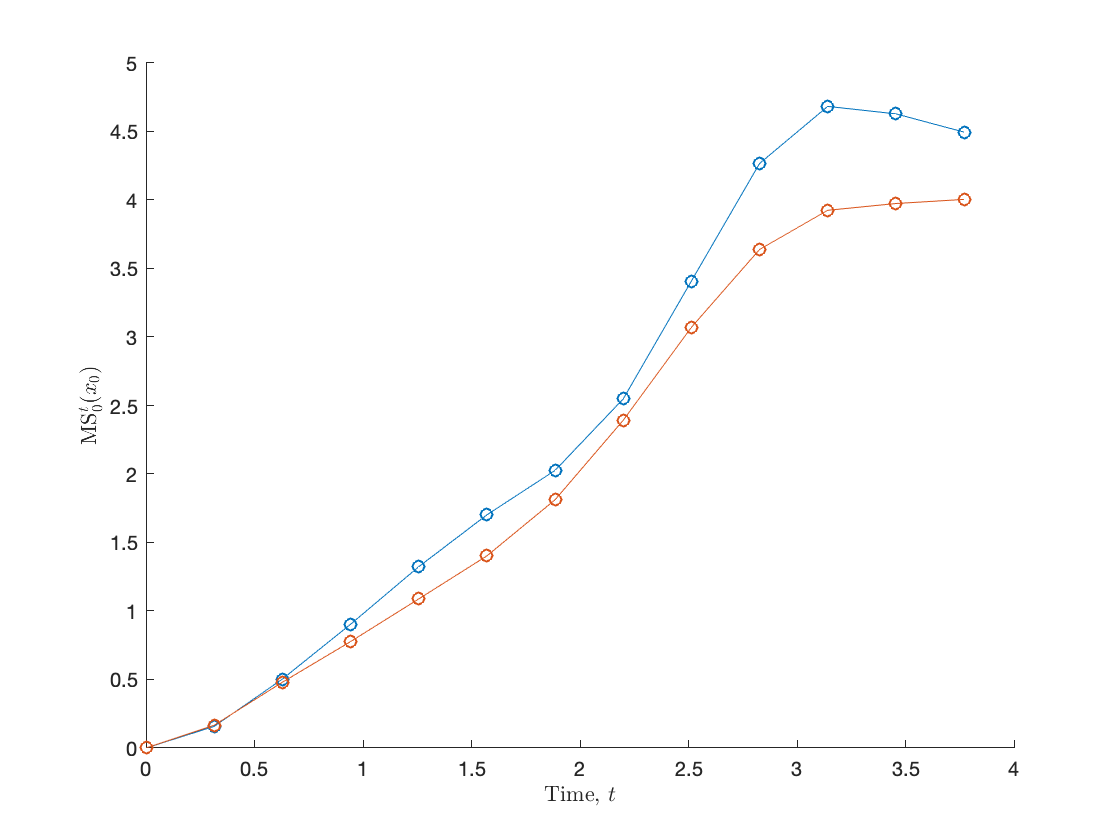


clf;
cla;
hold on;
plot(t1, uncertAtTime1, '-o');
plot(t2, uncertAtTime2, '-o');
xlabel('Time, $t$', 'Interpreter',"latex");
ylabel('MS$_0^{t}(x_0)$', 'Interpreter',"latex");

iv = [0, 3.4558];
temp = uncertEstimate(lDerivative, ic1, [1,1], iv, stepSize/10);

   111

     1   111

     1   111



disp(temp)

    4.7567



iv = [0, 3.7700];
%0:stepSize:3.770

%3.4558+stepSize
temp = uncertEstimate(lDerivative, ic1, [1,1], iv, stepSize/10);

   121

     1   121

     1   121



disp(temp)

    4.6355

